% Matrix containing the average accuracy of each model (columns) for each
% dataset (rows).
column_names = {'SVM_LIN', 'SVM_RBF', 'KNN', 'TREE'};
accuracy_tbl = array2table(nan(4, 4), 'VariableNames', column_names);

% Iterate over the 4 datasets
for ndataset=1:4

    switch ndataset
        case 1, load data/dataset1.mat
        case 2, load data/dataset2.mat
        case 3, load data/dataset3.mat
        case 4, load data/dataset4.mat
        otherwise
    end

    % Accuracy matrix for dataset ndataset and model
    accuracy_ntimes = array2table(nan(5, 4), 'VariableNames', column_names);

    for ntimes=1:5
        % stratified sampling
        idx_tr=[]; % Indexes training
        idx_te=[]; % Indexes test

        for nclass=1:2
            u=find(labels==nclass); % Find indexes of current label
            idx=randperm(numel(u)); % Permutate the found indexes
            % Select first half of shuffled indexes
            idx_tr=[idx_tr; u(idx(1:round(numel(idx)/2)))];
            % Select second half of shuffled indexes
            idx_te=[idx_te; u(idx(1+round(numel(idx)/2):end))];
        end

        % Select labels using training and test indexes
        labels_tr=labels(idx_tr);
        labels_te=labels(idx_te);
        % Select data using training and test indexes
        data_tr=data(idx_tr,:);
        data_te=data(idx_te,:);
        
        % training classifier(s)
        % train on training split, test on test split
        classifiers_tr={fitcsvm(data_tr,labels_tr,'KernelFunction','linear','KernelScale',1);
                        fitcsvm(data_tr,labels_tr,'KernelFunction','gaussian','KernelScale',0.1);
                        fitcknn(data_tr,labels_tr,'Distance','Euclidean','NumNeighbors',10);
                        fitctree(data_tr,labels_tr,'SplitCriterion','gdi','MaxNumSplits', 25);
        };

        % reversing role of training and test:
        % train on test split, test on train split
        classifiers_te={fitcsvm(data_te,labels_te,'KernelFunction','linear','KernelScale',1);
                        fitcsvm(data_te,labels_te,'KernelFunction','gaussian','KernelScale',0.1);
                        fitcknn(data_te,labels_te,'Distance','Euclidean','NumNeighbors',10);
                        fitctree(data_te,labels_te,'SplitCriterion','gdi','MaxNumSplits', 25);
        };

        % Compute accuracy for each model
        for model=1:4

            prediction1 = predict(classifiers_tr{model}, data_te);
            accuracy1 = mean(prediction1 == labels_te);

            prediction2 = predict(classifiers_te{model}, data_tr);
            accuracy2 = mean(prediction2 == labels_tr);

            accuracy = (accuracy1+accuracy2)/2;
            accuracy_ntimes{ntimes,model}=accuracy;
        end        
    end
    fprintf('Dataset number = %d ', ndataset);
    disp(accuracy_ntimes);
    accuracy_tbl{ndataset,:} = mean(accuracy_ntimes{:,:}, 'omitnan');
end

Dataset number = 1 

    SVM_LIN    SVM_RBF    KNN     TREE  
    _______    _______    ___    _______

       1       0.99667     1     0.99333
       1       0.99667     1     0.99333
       1             1     1     0.99333
       1             1     1     0.99333
       1       0.99667     1     0.99333



Dataset number = 2 

    SVM_LIN    SVM_RBF      KNN       TREE  
    _______    _______    _______    _______

    0.87667    0.79333    0.86667    0.84333
       0.89        0.8       0.88    0.83667
       0.88    0.81667    0.86667       0.85
    0.88333       0.81    0.87333    0.83667
    0.88667       0.82    0.87333    0.81333



Dataset number = 3 

    SVM_LIN    SVM_RBF      KNN       TREE  
    _______    _______    _______    _______

    0.66667    0.90667    0.91833    0.91667
    0.66667    0.91833      0.915    0.87167
    0.66667      0.905    0.91833    0.91167
    0.66667    0.92167    0.92333       0.92
    0.66667    0.91667    0.92167    0.90167



Dataset number = 4 

    SVM_LIN    SVM_RBF      KNN       TREE  
    _______    _______    _______    _______

    0.55167    0.96333    0.93833    0.95333
    0.58167    0.95667      0.945      0.965
    0.57333    0.95667    0.94667    0.95833
       0.57       0.95       0.95    0.96167
      0.535    0.95833    0.94167    0.96167



disp(accuracy_tbl)

    SVM_LIN    SVM_RBF      KNN       TREE  
    _______    _______    _______    _______

          1      0.998          1    0.99333
    0.88333      0.808      0.872      0.836
    0.66667    0.91367    0.91933    0.90433
    0.56233      0.957    0.94433       0.96



rank = rank_classifiers(accuracy_tbl)

rank =     1.5000    3.0000    1.5000    4.0000
    1.0000    4.0000    2.0000    3.0000
    4.0000    2.0000    1.0000    3.0000
    4.0000    2.0000    3.0000    1.0000


avg_rank = mean(rank, 1)

avg_rank =     2.6250    2.7500    1.8750    2.7500


[final_rank, ~] = tiedrank(avg_rank,1)

final_rank =     2.0000    3.5000    1.0000    3.5000


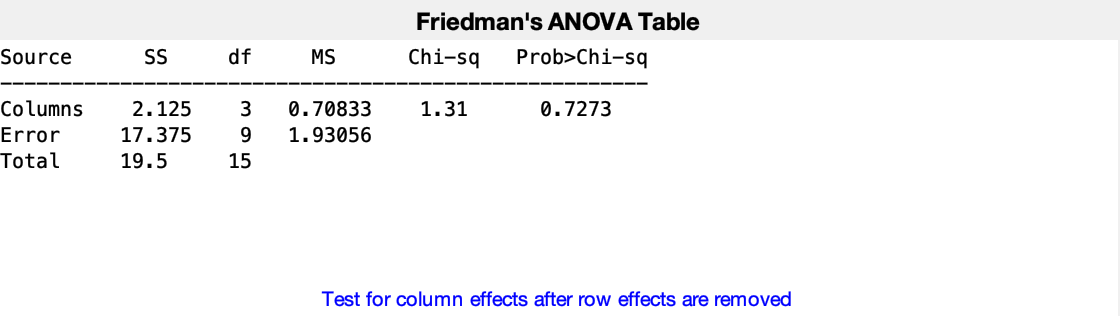

p = 0.7273

tbl = 4×6 cell array
    {'Source' }    {'SS'     }    {'df'}    {'MS'      }    {'Chi-sq'  }    {'Prob>Chi-sq'}
    {'Columns'}    {[ 2.1250]}    {[ 3]}    {[  0.7083]}    {[  1.3077]}    {[     0.7273]}
    {'Error'  }    {[17.3750]}    {[ 9]}    {[  1.9306]}    {0×0 double}    {0×0 double   }
    {'Total'  }    {[19.5000]}    {[15]}    {0×0 double}    {0×0 double}    {0×0 double   }


stats = struct with fields:
       source: 'friedman'
            n: 4
    meanranks: [2.3750 2.2500 3.1250 2.2500]
        sigma: 1.2748


[p, tbl, stats] = friedman(table2array(accuracy_tbl), 1)

% Number of datasets and algorithms
[num_datasets, num_algorithms] = size(accuracy_tbl)

num_datasets = 4

num_algorithms = 4

chi2_F = tbl{2, 5}

chi2_F = 1.3077

[F_ID, p_value_ID] = Iman_Davenport(accuracy_tbl, chi2_F)

F_ID = 0.3669

p_value_ID = 0.7788

allNormal = testNormality();

Not all datasets are normal!

Not all datasets are normal!

% Compute the critical difference (CD) value
q_05_4_classifiers = 2.569

q_05_4_classifiers = 2.5690

CD = sqrt(num_algorithms*(num_algorithms+1)/(6*num_datasets)) * q_05_4_classifiers

CD = 2.3452

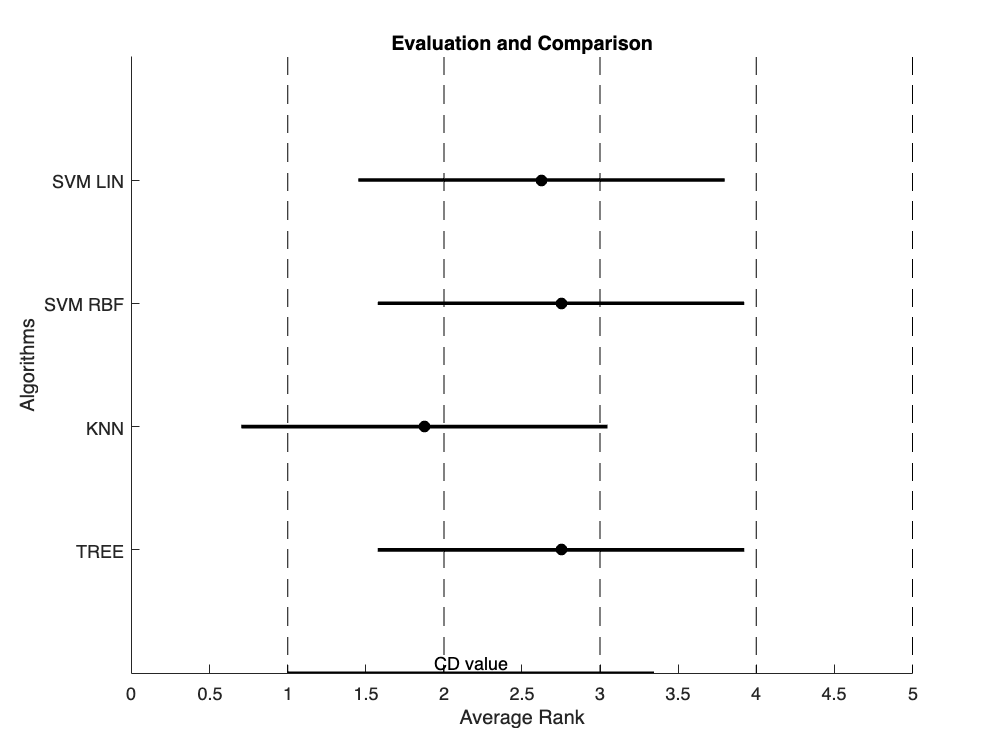

% Create the figure
figure;
hold on;

% Plot the average ranks
for i = 1:num_algorithms
    plot([avg_rank(i) - CD/2, avg_rank(i) + CD/2], [i i], 'k', 'LineWidth', 2);
    plot(avg_rank(i), i, 'ko', 'MarkerFaceColor', 'k');
end

% Set the Y-axis
set(gca, 'yTick', 1:num_algorithms);
set(gca, 'yTickLabel', {'SVM LIN', 'SVM RBF', 'KNN', 'TREE'});
set(gca, 'YDir','reverse'); % To match the given plot's direction

% Set the X-axis
xlim([0 5]);

% Labeling the CD value
cd_line = line([1, 1 + CD], [num_algorithms+1, num_algorithms+1], 'Color', 'k', 'LineWidth', 2);
text(1 + CD/2, num_algorithms+1, 'CD value', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');

% Optional: Add vertical dashed lines to delineate ranking zones
for i = 1:5
    line([i i], [0 num_algorithms+1], 'Color', 'k', 'LineStyle', '--', 'LineWidth', 0.5);
end

% Title and axis labels
title('Evaluation and Comparison');
xlabel('Average Rank');
ylabel('Algorithms');

hold off;

function ranked_accuracy = rank_classifiers(accuracy_matrix)
    % accuracy_matrix: Matrix of accuracy scores where rows represent datasets and columns represent classifiers

    % Get the number of datasets and classifiers
    [num_datasets, num_classifiers] = size(accuracy_matrix);

    % Initialize the ranked accuracy matrix
    ranked_accuracy = zeros(num_datasets, num_classifiers);

    % Iterate over each dataset
    for i = 1:num_datasets
        % Initialize the rank for the current dataset
        rank = 1;

        % Iterate over each classifier
        for j = 1:num_classifiers
            % Compare the accuracy of the current classifier with others
            for k = 1:num_classifiers
                if k ~= j && accuracy_matrix{i,j} < accuracy_matrix{i,k}
                    % If the accuracy of the current classifier is lower than another, increment the rank
                    rank = rank + 1;
                end
            end

            % Assign the rank to the corresponding classifier
            ranked_accuracy(i,j) = rank;
            % Reset the rank for the next classifier
            rank = 1;
        end

        % Get unique ranks for the current dataset
        unique_ranks = unique(ranked_accuracy(i,:));

        % Iterate over unique ranks
        for j = 1:length(unique_ranks)
            % Find classifiers with the current rank
            idx = find(ranked_accuracy(i,:) == unique_ranks(j));

            % If there are multiple classifiers with the same rank
            if numel(idx) > 1
                tot_rank = unique_ranks(j);
                for a = 1:(numel(idx)-1)
                    tot_rank = tot_rank + unique_ranks(j) + a;
                end
                % Assign the average rank to these classifiers
                ranked_accuracy(i,idx) = tot_rank/numel(idx);
            end
        end
    end
end

function [F_ID, p_value_ID] = Iman_Davenport(accuracy_tbl, chi2_F)
    % Determine the number of datasets and classifiers
    n = size(accuracy_tbl, 1); % Number of datasets
    k = size(accuracy_tbl, 2); % Number of classifiers

    % Calculate the Iman and Davenport statistic
    F_ID = ((n - 1) * chi2_F) / (n * (k - 1) - chi2_F);

    % Determine the significance (p-value)
    p_value_ID = 1 - fcdf(F_ID, k - 1, (k - 1) * (n - 1));
end

function allNormal = testNormality()
    % Assume all are normal initially
    allNormal = 1;

    for ndataset=1:4
        % Load each dataset
        switch ndataset
            case 1, load data/dataset1.mat
            case 2, load data/dataset2.mat
            case 3, load data/dataset3.mat
            case 4, load data/dataset4.mat
        end

        % Perform the Lilliefors test
        for i=1:size(data, 2)
            [h, p] = lillietest(data(:, i));

            % Check the hypothesis test result
            if h == 1 && p < 0.05
                % If any dataset is not normally distributed
                fprintf('Not all datasets are normal!')
                allNormal = 0;
                break;  % Exit the loop
            end
        end
    end
end